## 1) Load the data 

%% Initialization
clear ; close all; clc

load('MNIST.mat'); % training data stored in arrays X, y

[numSample,numFeature]=size(XTrain);
whos

  Name               Size                Bytes  Class     Attributes

  XTest           1000x400             3200000  double              
  XTrain          4000x400            12800000  double              
  numFeature         1x1                     8  double              
  numSample          1x1                     8  double              
  yTest           1000x1                  8000  double              
  yTrain          4000x1                 32000  double              



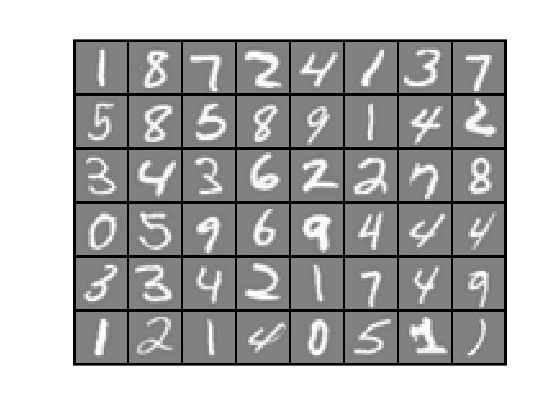




% Randomly select 48 data points to display
rand_indices = randperm(numSample,48);  %returns a row vector containing a random permutation of the integers from 1 to n inclusive.
image_sel = XTrain(rand_indices, :);
displayData(image_sel);  

## 2) Y data preparation

We need to generate 10 out nodes in output layer.     y=${\left[\begin{array}{c}
\begin{array}{c}
y_1 \\
y_2 
\end{array}\\
\begin{array}{c}
\dots \\
y_{10} 
\end{array}
\end{array}\right]}$                           

The label ‘1’= ${\left[\begin{array}{c}
\begin{array}{c}
1\\
0
\end{array}\\
\begin{array}{c}
\dots \\
0
\end{array}
\end{array}\right]}$, the label ‘2’ =${\left[\begin{array}{c}
\begin{array}{c}
0\\
1
\end{array}\\
\begin{array}{c}
\dots \\
0
\end{array}
\end{array}\right]}$, and so on.

%% add code 
%write code to conver labels into the multiple nodes forms described above: 


%add code to find the number of lable in y
numlabels = size(unique(yTrain),1);





%1)convert yTrain data and save the multiple output form as 'mul_yTrain'

%add code to get yTraing data size info
[M,n] = size(yTrain);

%add code
% repeat a vector [1, ..., numlabes] mumSample x 1 times

tmpY1 = repmat([1:numlabels], M,1);
  
%add code
 %repeat y vector 1 by num_labels
 
tmpY2 = repmat(yTrain,1,numlabels);


mul_yTrain = (tmpY1 == tmpY2);
%2)convert yTest data and save the multiple output form as 'mul_yTest'



%add code
%get yTest data size info
[M_Test,n_Test] = size(yTest);



%add code
% repeat a vector [1, ..., numlabes] mumTest  x 1 times

tmpYT1 = repmat([1:numlabels], M,1);;


%add code     
 %repeat y vector 1 by num_labels
 tmpYT2 = repmat(yTrain,1,numlabels);
 
 %add code to conver the yTest into a row vector form 

mul_yTest = (tmpYT1 == tmpYT2);
 





**3) Using the Neural Network Pattern Recognition App**

If needed, open the Neural Network Start GUI with this command:`nnstart`

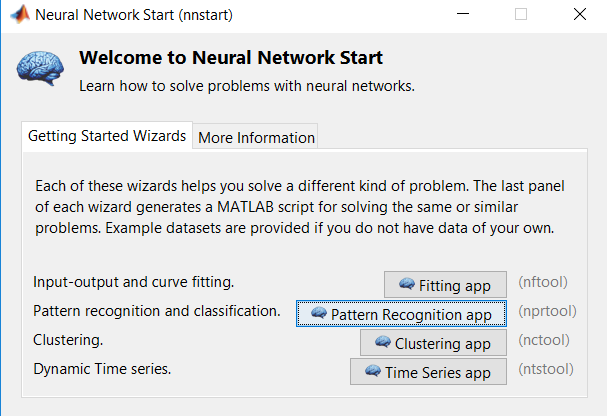

Select Pattern recognition app and follow the tutorial  in the Lab5 hand out.

%% =================  Implement Predict =================
%  After training the neural network, we would like to use it to predict
%  the labels. The function "myNeuralNetworkFunction" is generated by the Matlab APP. 
% Use the function to predict the labels of the test set.
% Calculate the test accuracy.

% add code to calculate the neural net accuracy on the test data using the function gnerated by the APP.



H = myNeuralNetworkFunction(XTest);
[val, Test_prediction] = max(H, [], 2);
fprintf('\nTesting Accuracy: %f\n', mean(double(Test_prediction == yTest)) * 100);


Testing Accuracy: 92.900000
